# Practice Adjusting Image Contrast

In this reading, you'll practice the image contrast adjustment techniques presented in "Improving Image Contrast" with grayscale and color images.

## Image Histograms

Image histograms show how many pixels of each intensity value are in an image. As you have seen, for 8-bit grayscale images, the intensity values range from 0 to 255. However, the following image of an ankle x-ray is 16-bit, so the intensities range from 0 to 65535 ($2^{16}$ - 1). Read in the image and visualize these intensities with `imhist:`

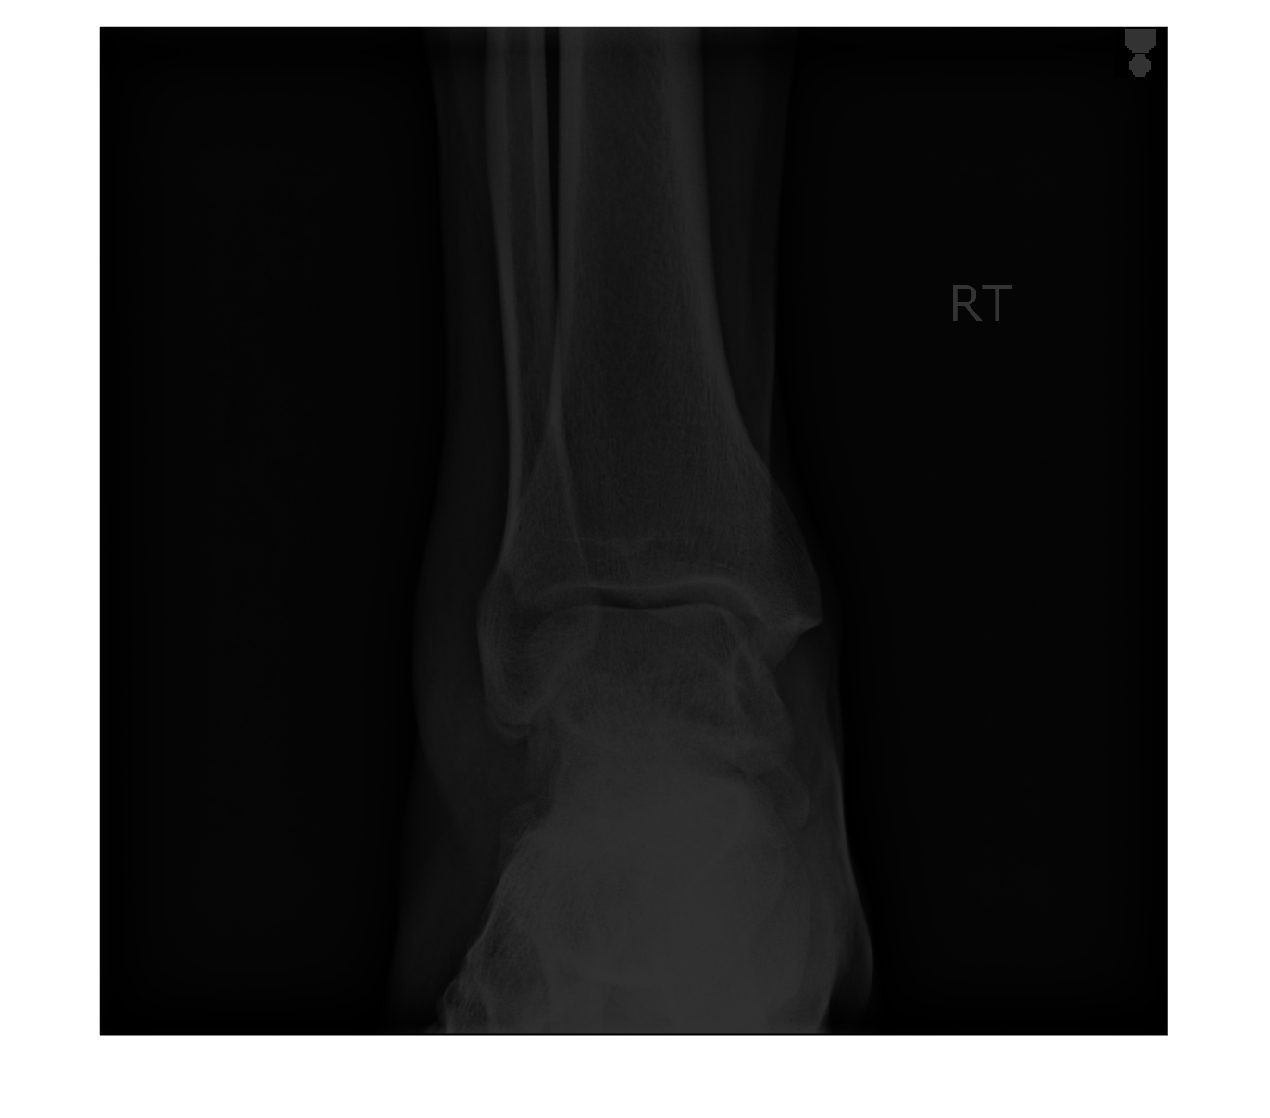

img = imread("ankleXray.png");
imshow(img)

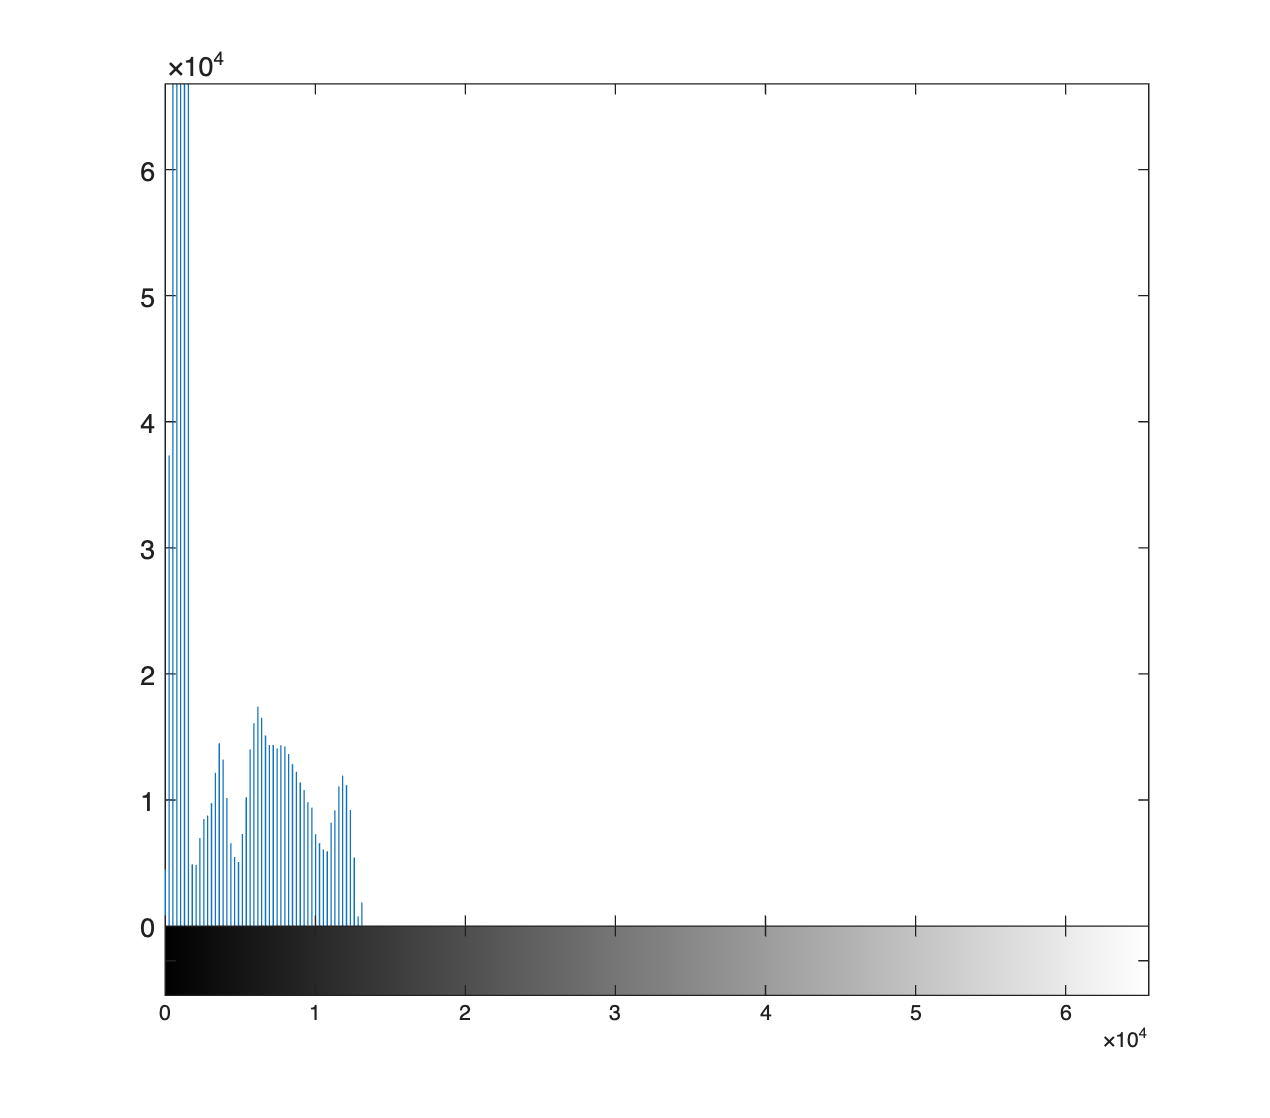

imhist(img)

The histogram is scaled to allow brightness levels with fewer pixels to be seen even though they have far fewer pixels than the highest peaks. Change the y-axis limits to show the entire histogram:

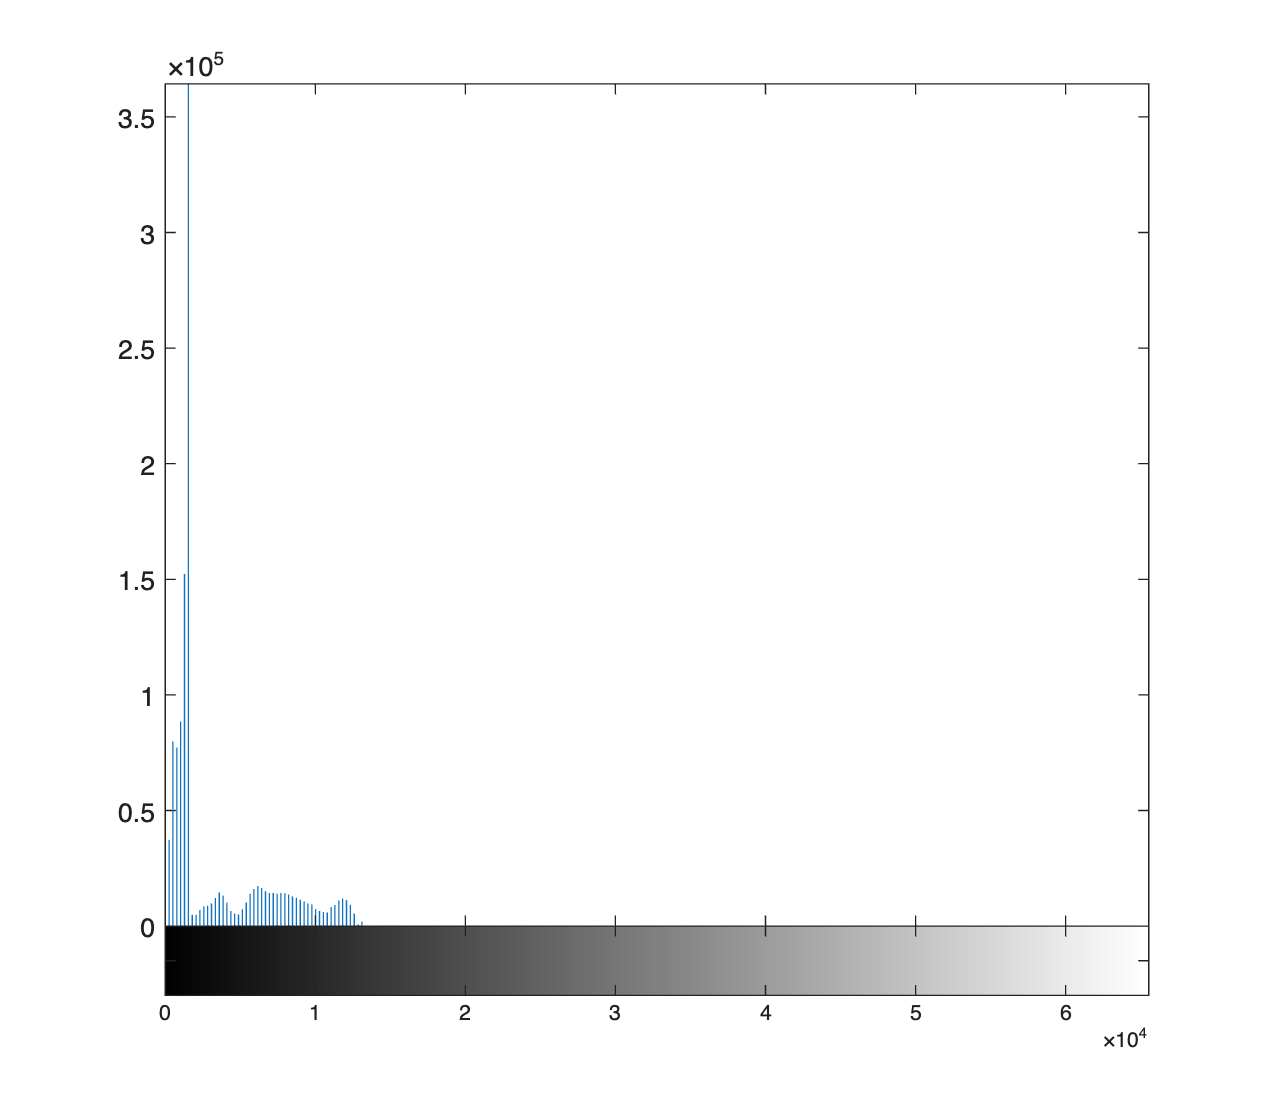

imhist(img)
ylim([0 Inf])

You can see from the histogram that there are some very high peaks in the low intensity region, i.e. dark regions of the image.

## Adjusting Histograms to Increase Image Contrast

MATLAB contains several methods for changing image contrast. These include:

- `imadjust` linearly stretches the histogram to use the full range of available values.

- `histeq` changes intensity values to utilize the full range of values more equally.

- `adapthisteq` breaks the image into tiles and equalizes the histogram for each tile, then blends the results together to produce the final image.

The choice of which of these methods to use will depend on the image.  Here is an example of all three methods being applied to the ankle image above and the resulting histograms. If the output is too small, you can open it in a figure window with the arrow that appears in the top right corner.

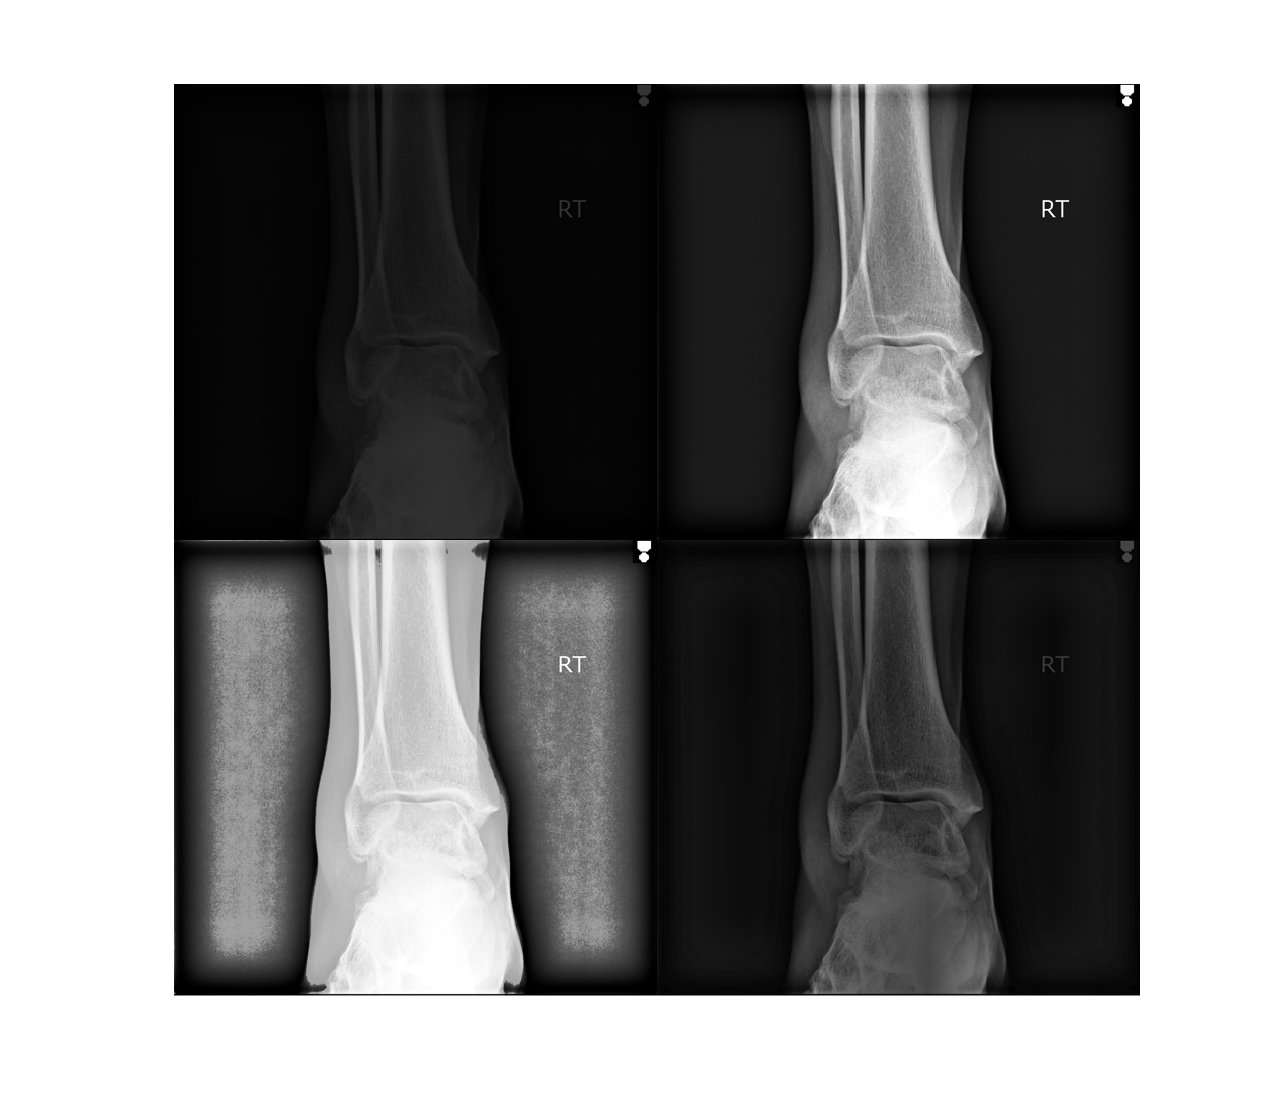

imgAdj = imadjust(img);
imgEq = histeq(img);
imgAdapt = adapthisteq(img);
montage({img, imgAdj, imgEq, imgAdapt})

Take a look at the histograms of all the techniques that you applied. 

### `imadjust`

The `imadjust` function scales the brightness values to use the entire available range.

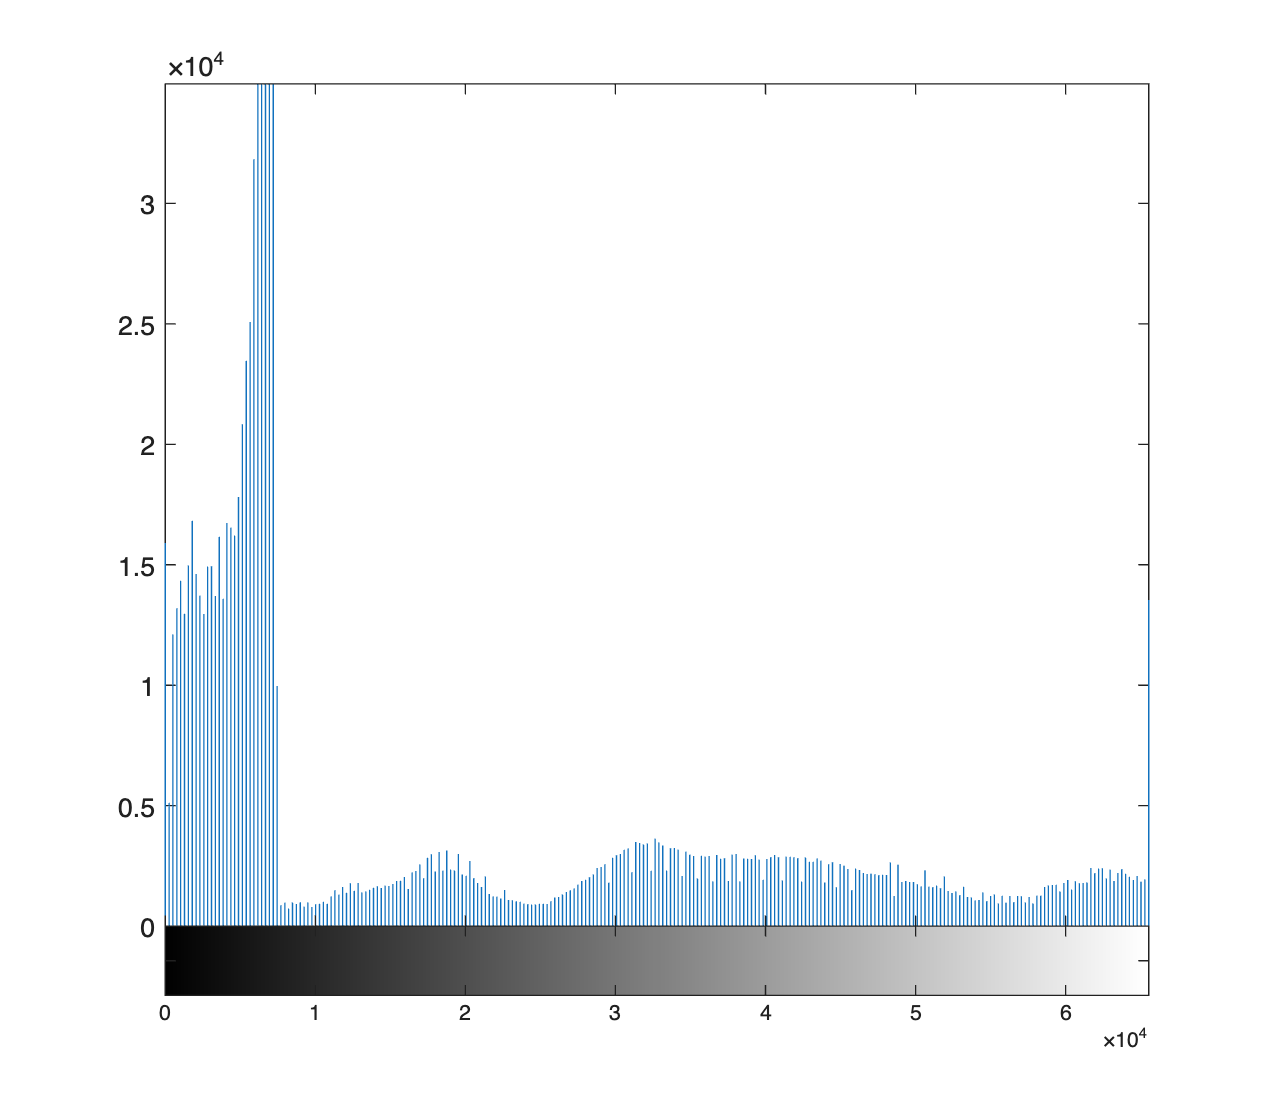

imhist(imgAdj); 

### `histeq`

The `histeq` function attempts to use all of the available brightness levels equally.  While there are still high peaks, the histogram is overall flatter.  

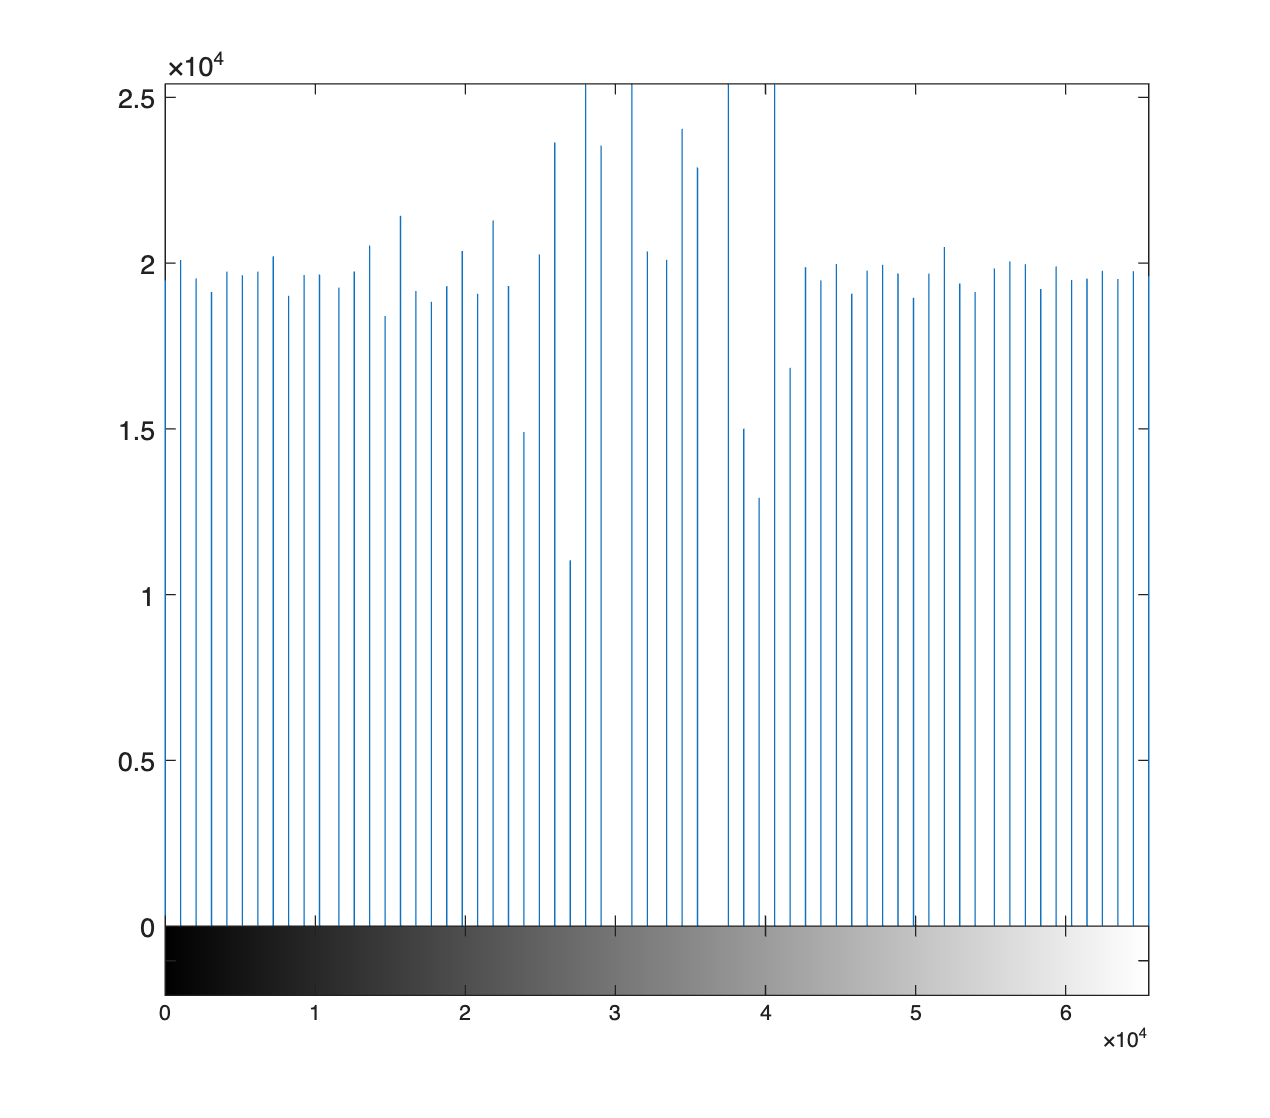

imhist(imgEq)

### `adapthisteq`

The `adapthisteq` function's behavior is more complex than the previous adjustment methods. Since the image is adjusted in pieces instead of as a single unit, the effect on the histogram is not as uniform.

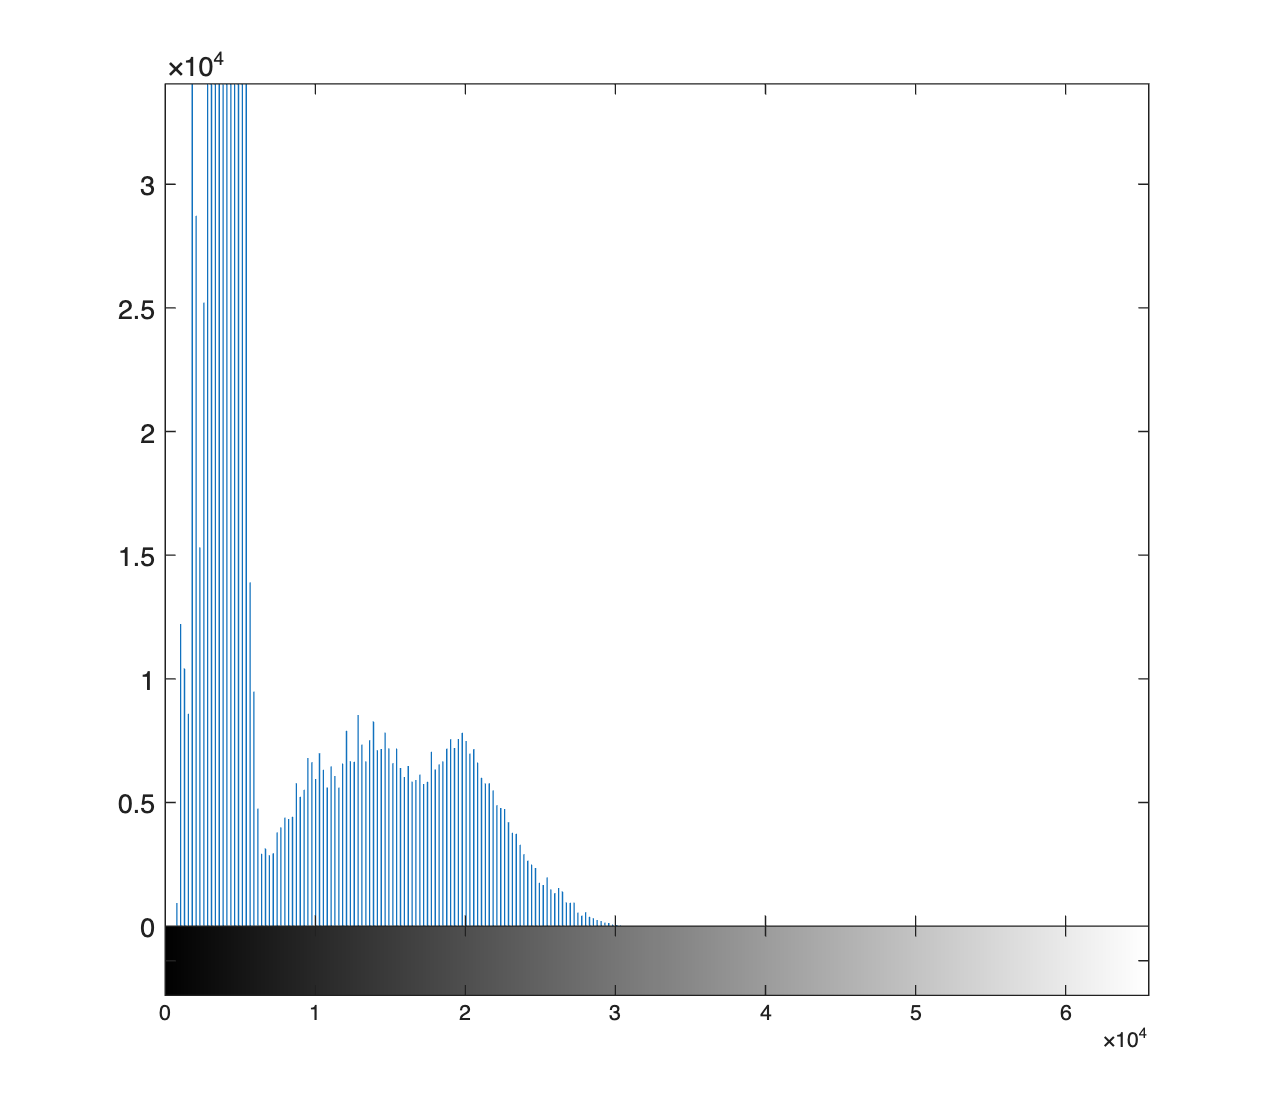

imhist(imgAdapt)

### Combining Techniques to Improve Contrast

From the 3 techniques covered so far, `imadjust` gives the best result for this image. However, you can improve the contrast even more. Try combining two different techniques by using the dropdown menus to select two contrast adjustment methods. Which combination looks best? In the video, you saw first `imadjust` and then `adapthisteq` works great for this image. Notice that if you reverse the order, the results are not as good. 

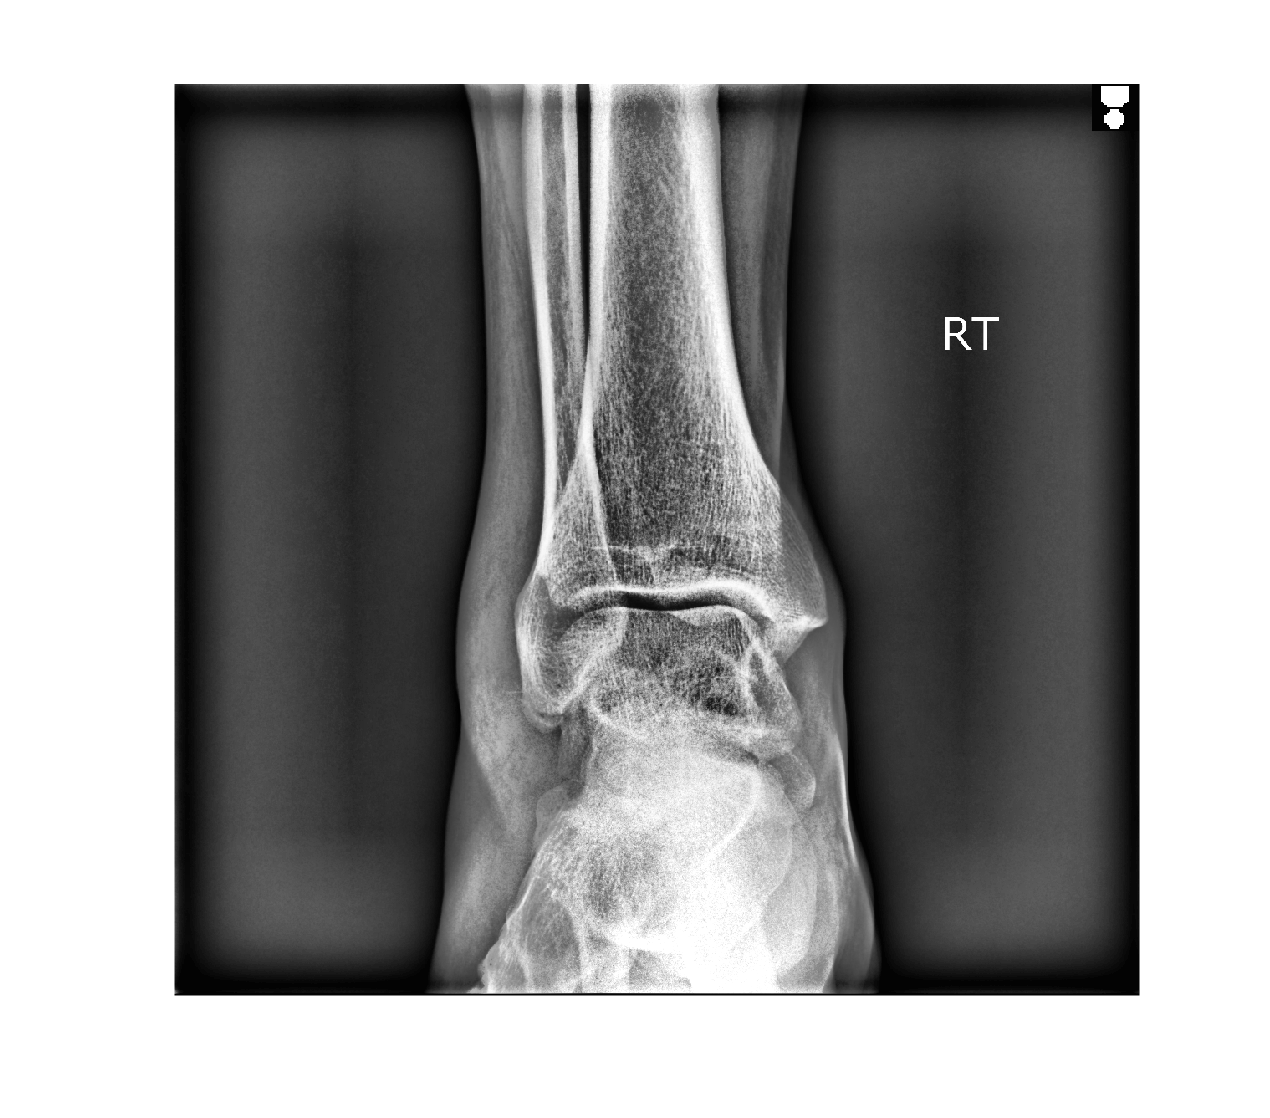

img1 = imadjust(img);
img2 = adapthisteq(img1);
imshow(img2)

### Exploring Image Contrast

Now that you have seen the effectiveness of combining techniques, use the dropdown menu to apply to apply the steps to other grayscale images. 

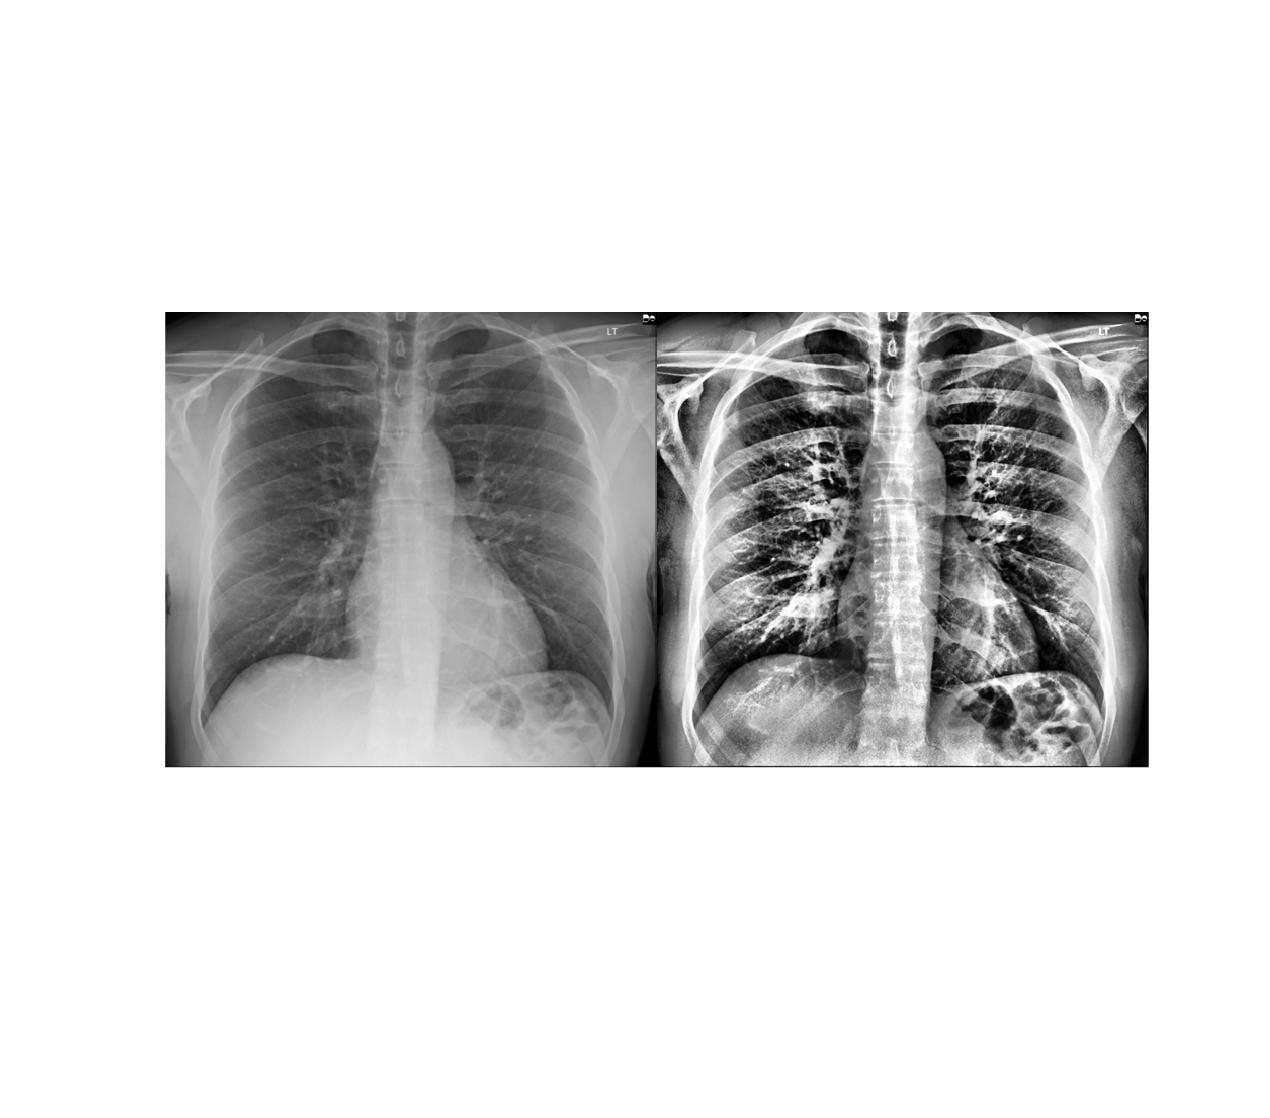

imgGray = imread("chestXray.tif"); 
imgGray1 = adapthisteq(imgGray);
imgGray2 = adapthisteq(imgGray1);
montage({imgGray,imgGray2}) 

## Adjusting Contrast in Color Images

Contrast adjustment can be performed on color images as well. However, adjusting RGB images requires additional steps because changes to individual color channels (red, green, or blue) can change the image in unexpected ways. Instead, you'll get better results by converting the image into a different color scale, such as HSV:

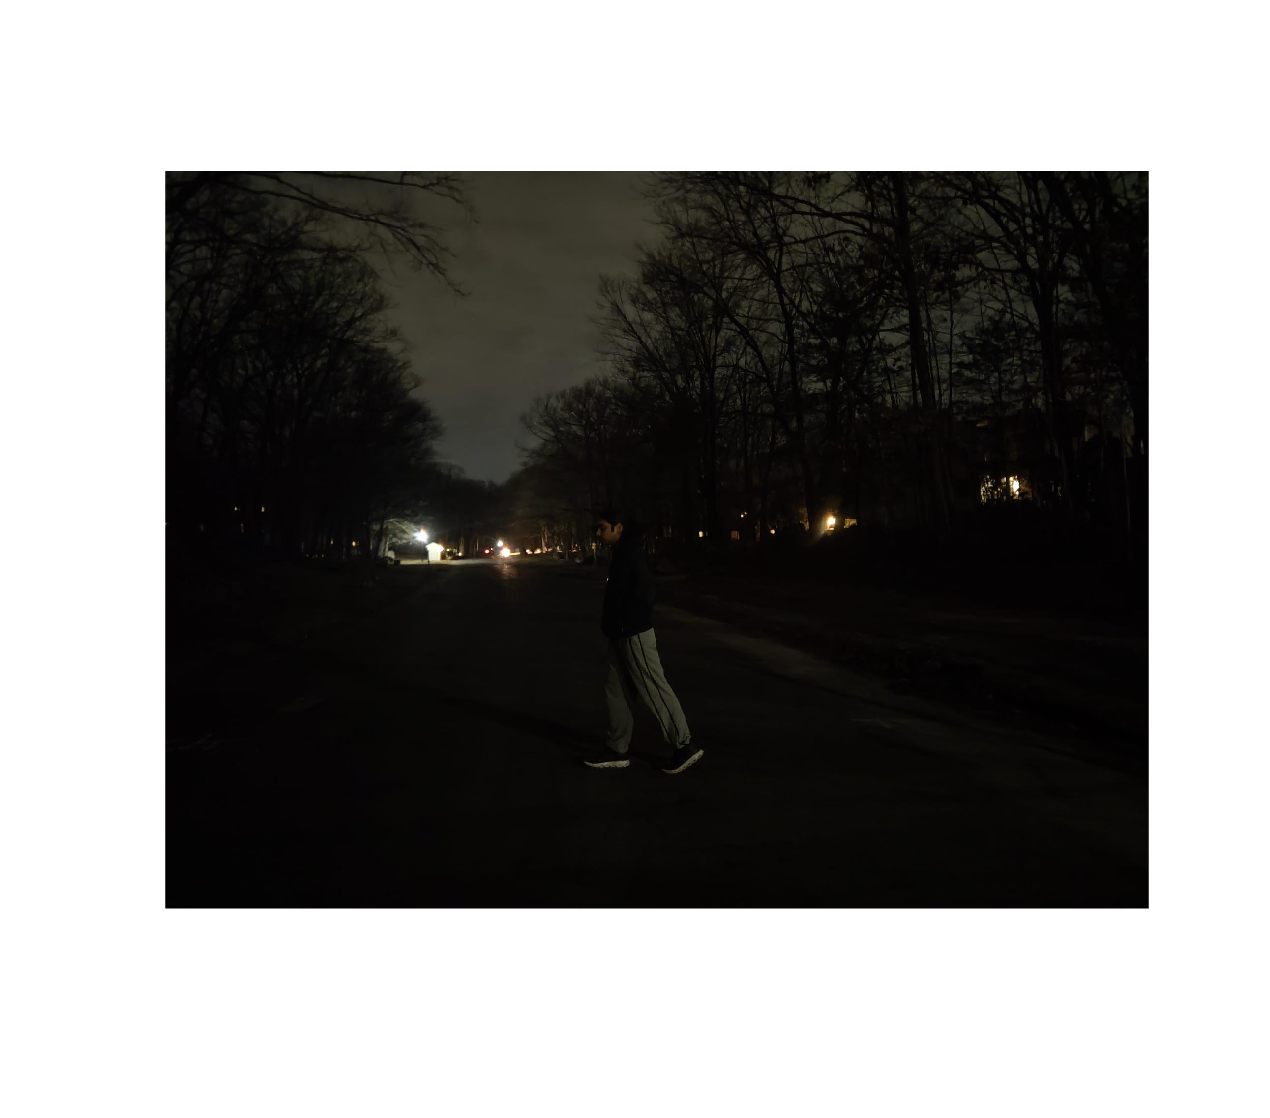

% Poor-visibility image of a pedestrian at night
imgRGB = imread("low_light_pedestrian.png");
imshow(imgRGB);

imgHSV = rgb2hsv(imgRGB);

Because the value channel determines an image's brightness, adjusting the value channel will have the biggest effect on the image's contrast.

The histogram for the value channel shows that this image's pixels are mostly dark, with intensities concentrated at the low end of the histogram.

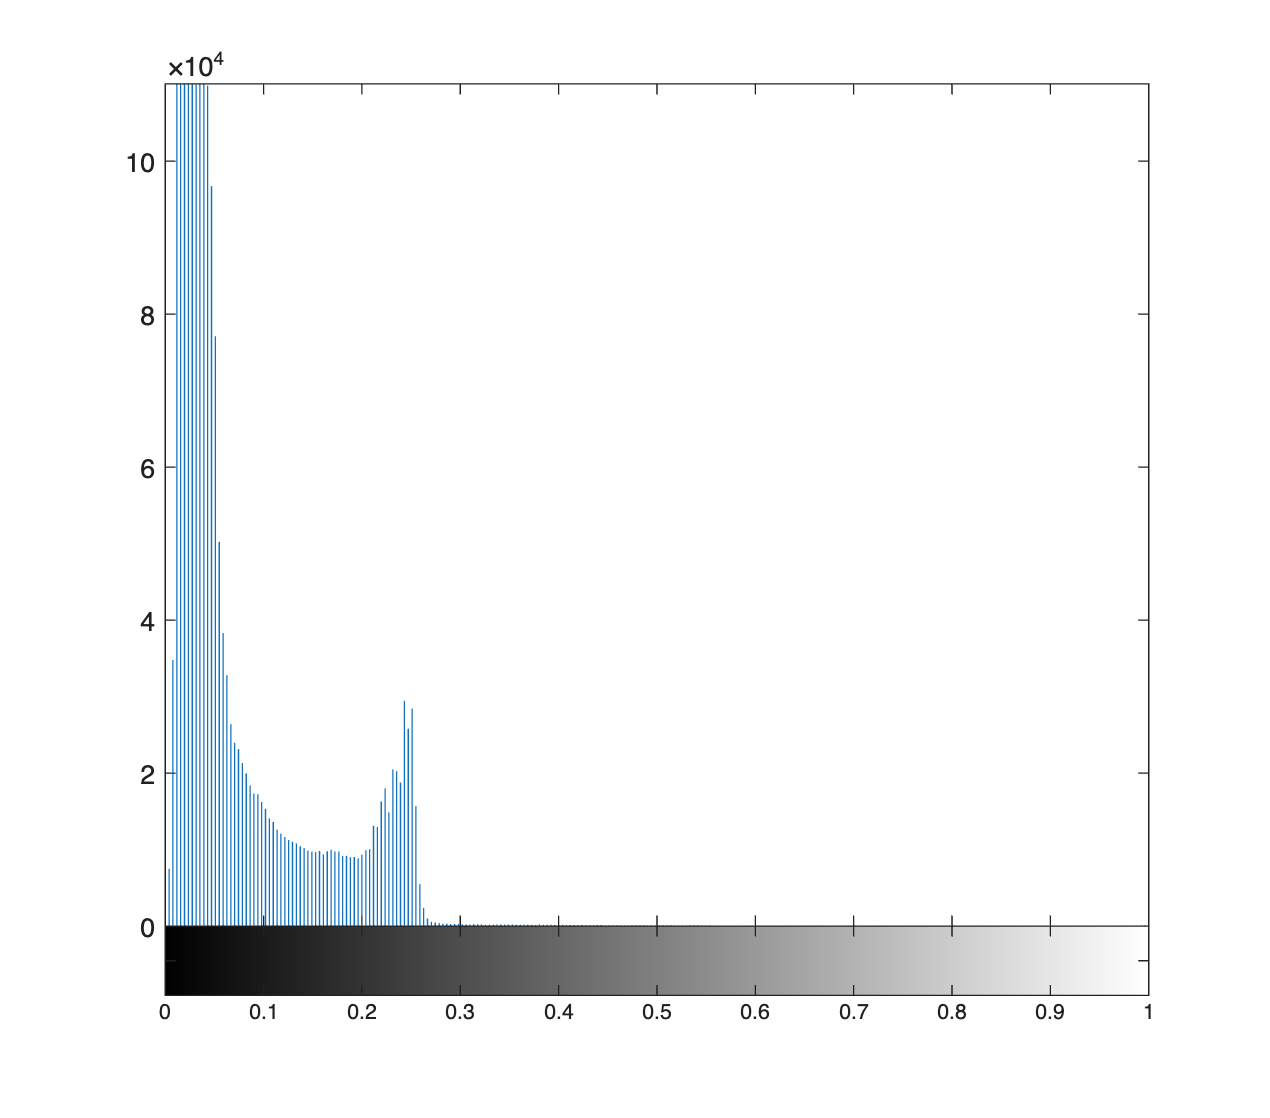

imhist(imgHSV(:,:,3)) % value channel

### Adjusting the Value Channel

Use the `imadjust` function to stretch the value channel to make more use of the whole range. 

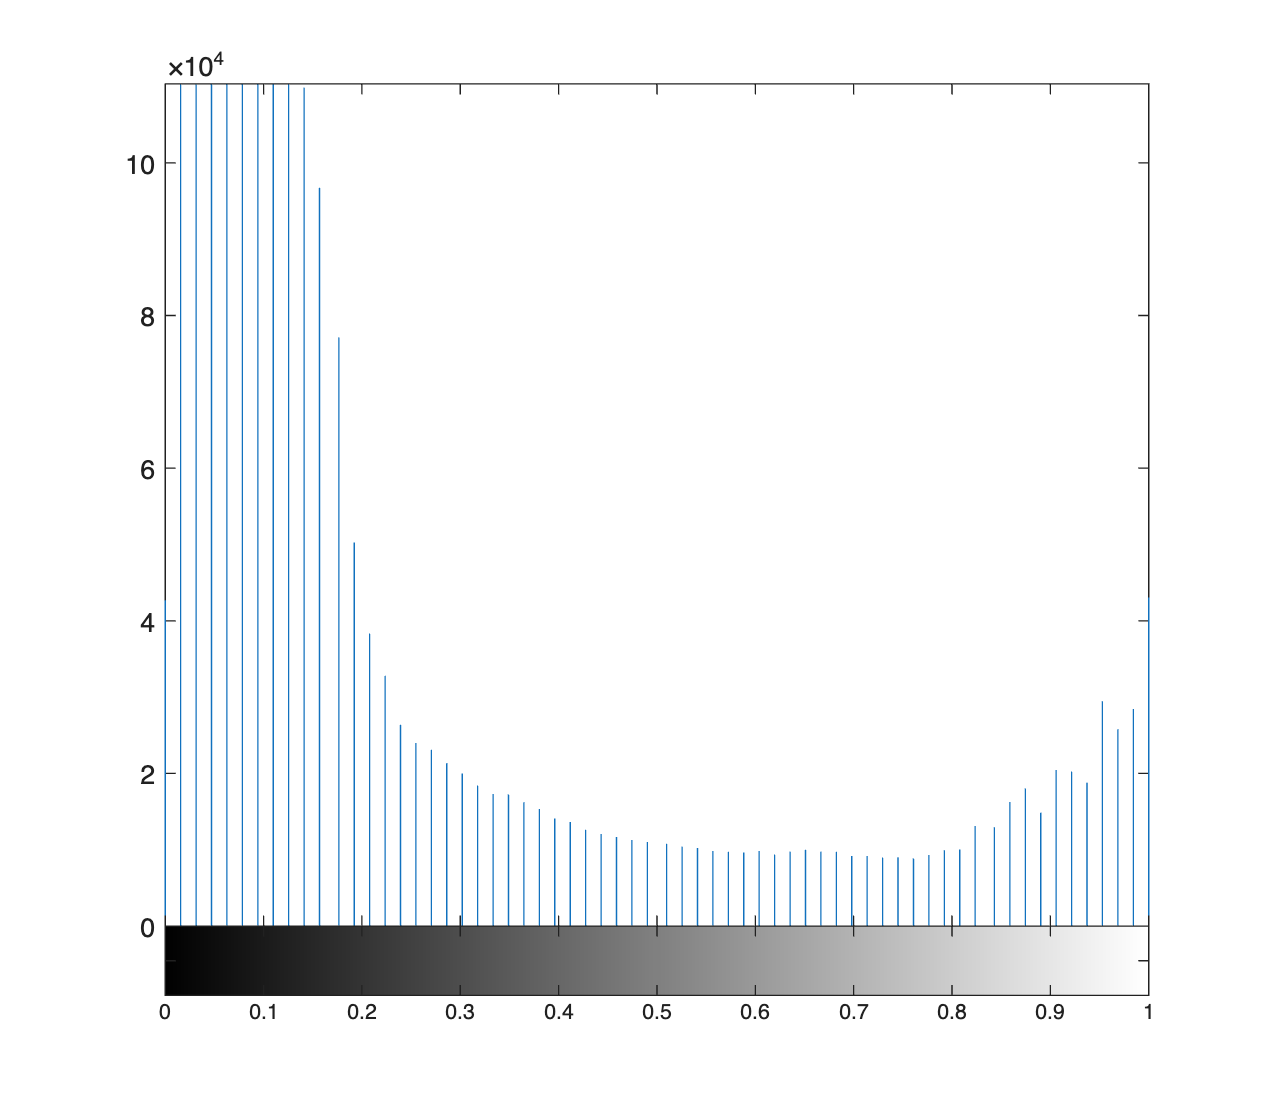

imgHSV(:,:,3) = imadjust(imgHSV(:,:,3));
imhist(imgHSV(:,:,3))

This improves the image contrast. Remember to convert the image from double to uint8 after the HSV to RGB transformation. 

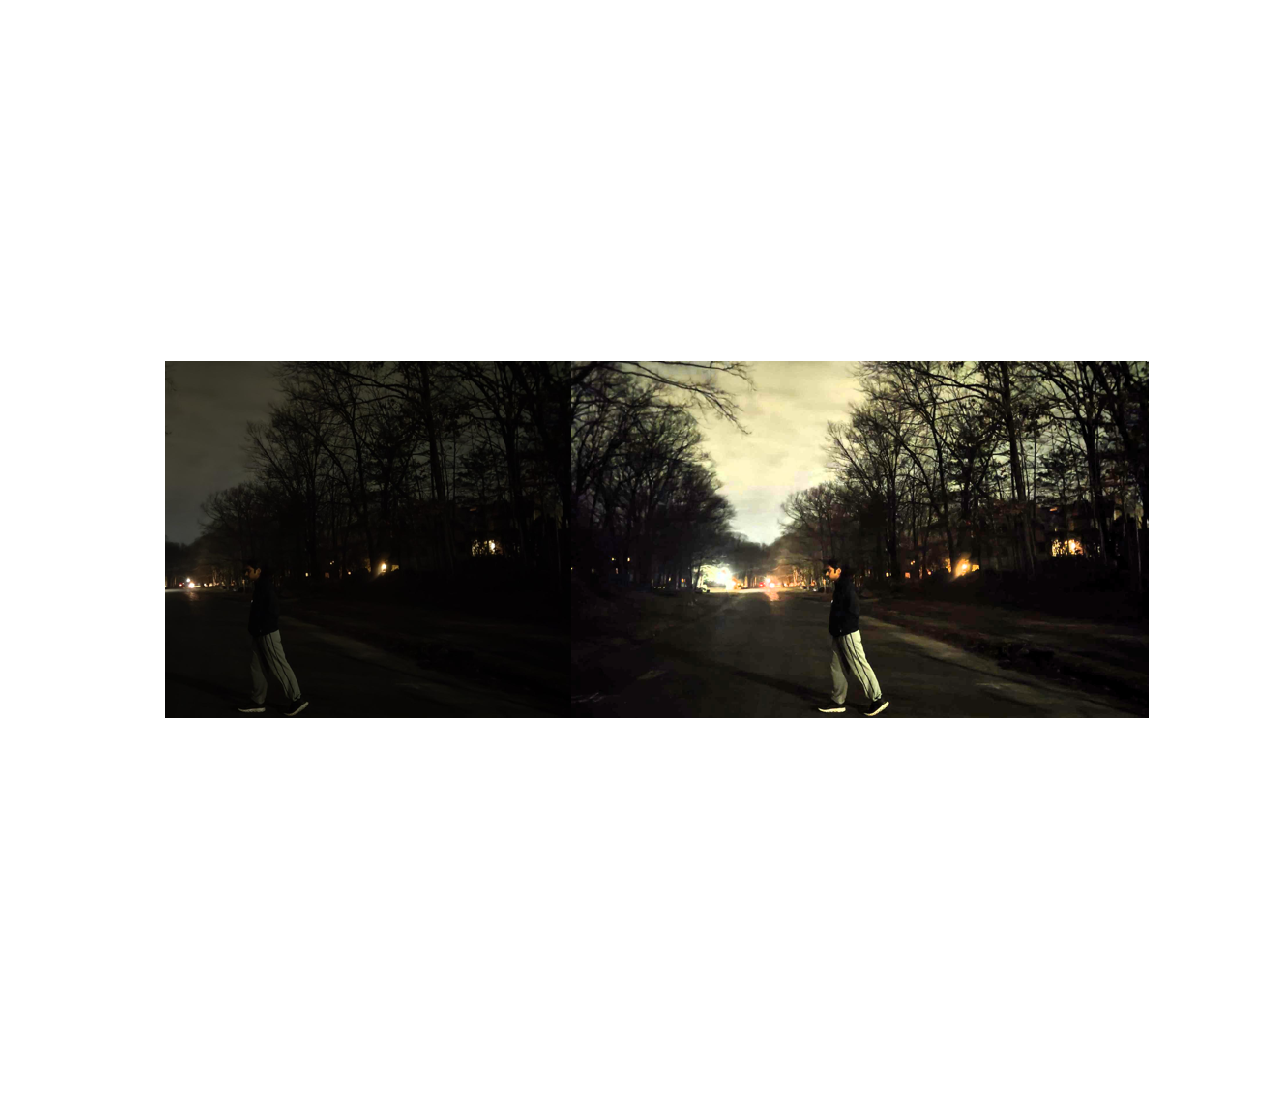

pedAdj = hsv2rgb(imgHSV);
pedAdj = im2uint8(pedAdj);
montage({imgRGB, pedAdj})

### Combining Adjustment Methods

Try combining contrast adjustment methods and visualizing the effect on the color image.

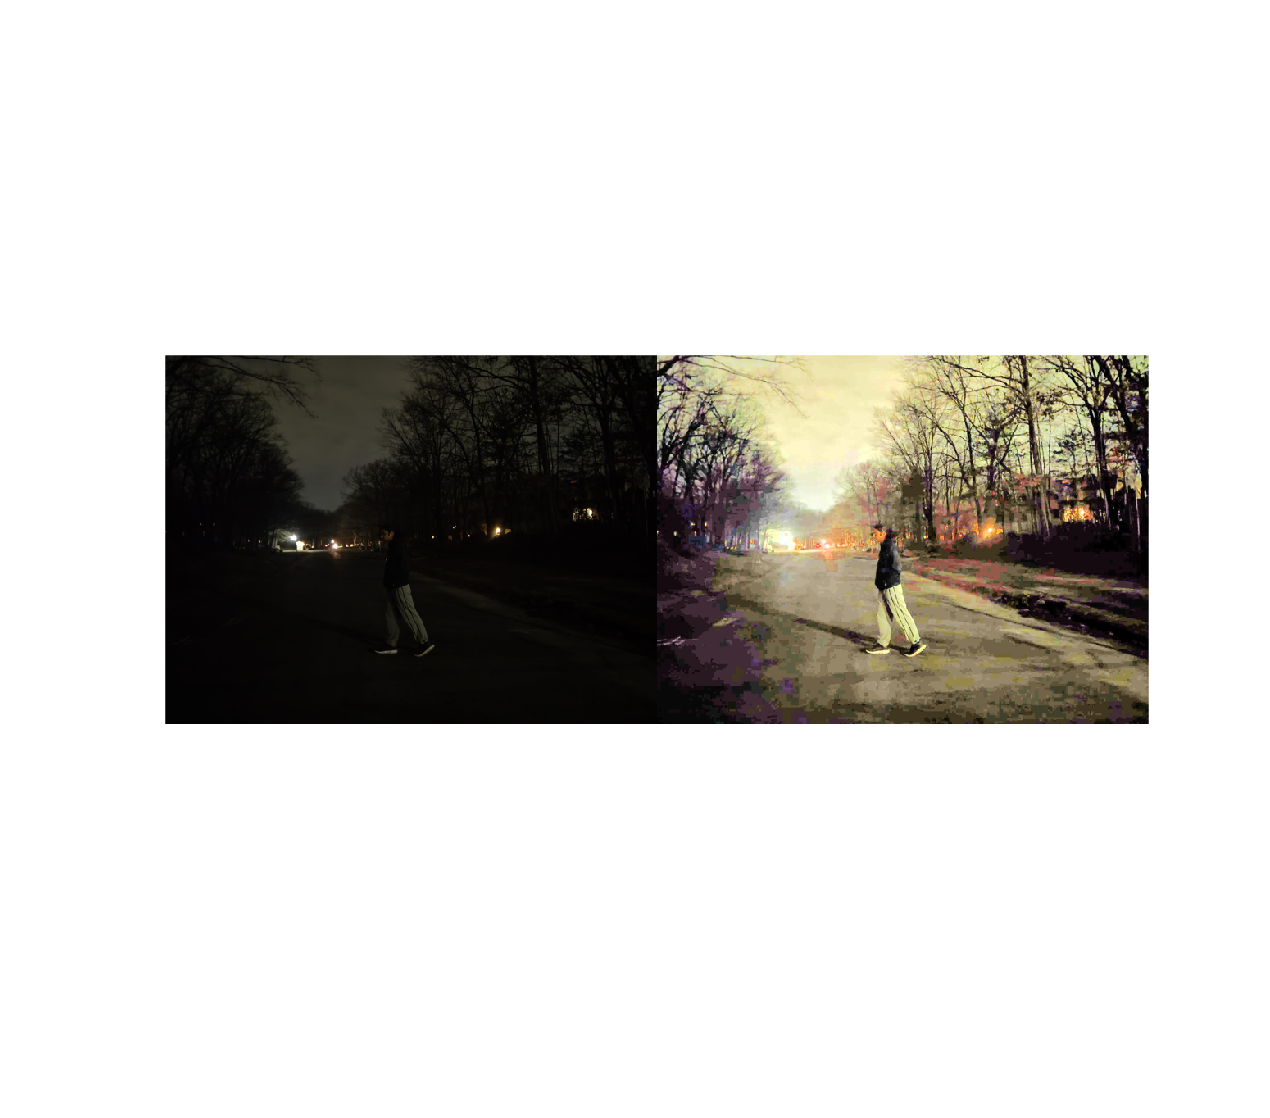

% Copying over the hue and saturation values, which will not change:
imgHSV1 = imgHSV;
imgHSV2 = imgHSV;

% Combining adjustment methods on the value channel
imgHSV1(:,:,3) = imadjust(imgHSV(:,:,3));
imgHSV2(:,:,3) = histeq(imgHSV1(:,:,3));

imgAdj = hsv2rgb(imgHSV2);
imgAdj = im2uint8(imgAdj);
montage({imgRGB, imgAdj})

*Copyright 2024 The MathWorks, Inc.*